addpath('..\common\')
%You can use this live script to generate your own tracking scenario and apply the single 
%object trackers you have implemented. Try to compare the estimation performance of
%different trackers, from simple scenario with linear motion/measurement model, high 
%object detection probability and low clutter rate to more complex scenario with 
%nonlinear motion/measurement model, low detection probability and high clutter rate. 
%In complex scenarios, it should be easy to verify that, on average, the Gaussian sum
%filter has the best performance. We also encourage you to tune the different model 
%parameters and to observe how they affact the tracking performance. 
%You might also be interested in writting your own plotting function to illustrate 
%the estimation uncertainty of the object state and study how it changes over time. 

clear; close all; clc
dbstop if error


%Choose object detection probability
P_D = 0.6;
%Choose clutter rate
lambda_c = 10;

%Choose linear or nonlinear scenario
scenario_type = 'nonlinear';

%Create tracking scenario
switch(scenario_type)
    case 'linear'
        %Create sensor model
        range_c = [-1000 1000;-1000 1000];
        sensor_model = modelgen.sensormodel(P_D,lambda_c,range_c);
        
        %Create ground truth model
        nbirths = 1;
        K = 100;
        initial_state.x = [0; 0; 10; 10];
        initial_state.P = eye(4);
        ground_truth = modelgen.groundtruth(nbirths,initial_state.x,1,K+1,K);
        
        %Create linear motion model
        T = 1;
        sigma_q = 5;
        motion_model = motionmodel.cvmodel(T,sigma_q);
        
        %Create linear measurement model
        sigma_r = 10;
        meas_model = measmodel.cvmeasmodel(sigma_r);
        
    case 'nonlinear'
        %Create sensor model
        %Range/bearing measurement range
        range_c = [-1000 1000;-pi pi];
        sensor_model = modelgen.sensormodel(P_D,lambda_c,range_c);
        
        %Creat ground truth model
        nbirths = 1;
        K = 100;
        initial_state.x = [0; 0; 10; 0; pi/180];
        initial_state.P = diag([1 1 1 1*pi/180 1*pi/180].^2);
        ground_truth = modelgen.groundtruth(nbirths,initial_state.x,1,K+1,K);
        
        %Create nonlinear motion model (coordinate turn)
        T = 1;
        sigmaV = 1;
        sigmaOmega = pi/180;
        motion_model = motionmodel.ctmodel(T,sigmaV,sigmaOmega);
        
        %Create nonlinear measurement model (range/bearing)
        sigma_r = 5;
        sigma_b = pi/180;
        s = [300;400];
        meas_model = measmodel.rangebearingmeasmodel(sigma_r, sigma_b, s);
end

obj = struct with fields:
          pdf_c: 7.9577e-05
            P_D: 0.6000
       lambda_c: 10
        range_c: [2×2 double]
    intensity_c: 7.9577e-04


%Generate true object data (noisy or noiseless) and measurement data
ifnoisy = 0;
objectdata = objectdatagen(ground_truth,motion_model,ifnoisy);
measdata = measdatagen(objectdata,sensor_model,meas_model);


%Single object tracker parameter setting
P_G = 0.999;            %gating size in percentage
w_min = 1e-3;           %hypothesis pruning threshold
merging_threshold = 2;  %hypothesis merging threshold
M = 100;                %maximum number of hypotheses kept in MHT
density_class_handle = feval(@GaussianDensity);    %density class handle
tracker = singleobjectracker();
tracker = tracker.initialize(density_class_handle,P_G,meas_model.d,w_min,merging_threshold,M);

%Nearest neighbour filter
nearestNeighborEstimates = nearestNeighbourFilter(tracker, initial_state, measdata, sensor_model, motion_model, meas_model);
nearestNeighborRMSE = RMSE(nearestNeighborEstimates,objectdata.X);

%Probabilistic data association filter
probDataAssocEstimates = probDataAssocFilter(tracker, initial_state, measdata, sensor_model, motion_model, meas_model);
probDataAssocRMSE = RMSE(probDataAssocEstimates,objectdata.X);

%Gaussian sum filter
GaussianSumEstimates = GaussianSumFilter(tracker, initial_state, measdata, sensor_model, motion_model, meas_model);
GaussianSumRMSE = RMSE(GaussianSumEstimates,objectdata.X);

X = sprintf('Root mean square error: Nearest neighbour: %.3f; Probabilistic data association: %.3f; Gaussian sum filtering: %.3f.'...
    ,nearestNeighborRMSE,probDataAssocRMSE,GaussianSumRMSE);
disp(X)

Root mean square error: Nearest neighbour: 3.743; Probabilistic data association: 3.730; Gaussian sum filtering: 3.741.


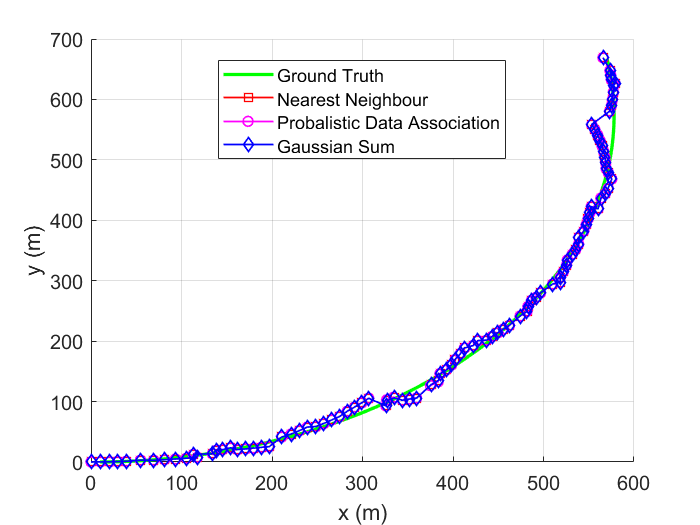

%Ploting
true_state = cell2mat(objectdata.X');
NN_estimated_state = cell2mat(nearestNeighborEstimates');
PDA_estimated_state = cell2mat(probDataAssocEstimates');
GS_estimated_state = cell2mat(GaussianSumEstimates');

figure
hold on
grid on

plot(true_state(1,:), true_state(2,:), 'g','Linewidth', 2)
plot(NN_estimated_state(1,:), NN_estimated_state(2,:), 'r-s' , 'Linewidth', 1)
plot(PDA_estimated_state(1,:), PDA_estimated_state(2,:), 'm-o' , 'Linewidth', 1)
plot(GS_estimated_state(1,:), GS_estimated_state(2,:), 'b-d' , 'Linewidth', 1)

xlabel('x (m)')
ylabel('y (m)')
legend('Ground Truth','Nearest Neighbour', 'Probalistic Data Association', 'Gaussian Sum', 'Location', 'best')

set(gca,'FontSize',12)